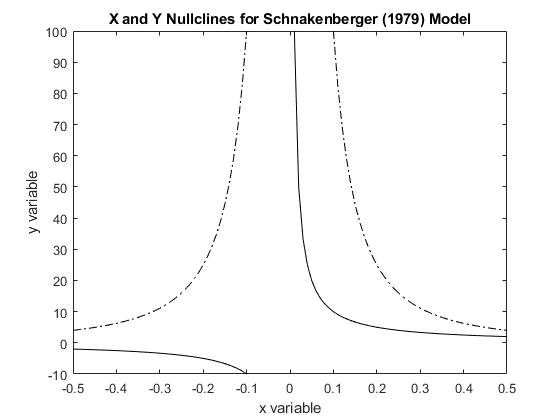

% 2D Data
a = 1;
x = -0.5:0.01:0.5; %define a range for x
yxnull = 1./x;
yynull = a./(x.^2);
plot(x,yxnull,'k'); %Make solid line
hold on
plot(x,yynull,'k-.'); %Make dash-dot line
axis([-0.5 0.5 -10 100])
xlabel('x variable');
ylabel('y variable');
title('X and Y Nullclines for Schnakenberger (1979) Model');

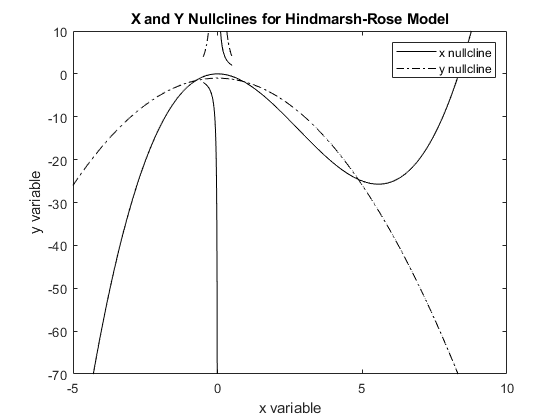

% Saving figures
a = 0.3;
b = 2.5;
c = -1.;
d = 1.0;
x = -5:0.01:10; %define a range for x
yxnull = a.*x.^3 - b.*x.^2; %create x nullcline
yynull = -d.*x.^2 + c; %create y nullcline
plot(x,yxnull,'k');
hold on
plot(x,yynull,'k-.');
xlabel('x variable')
ylabel('y variable');
title('X and Y Nullclines for Hindmarsh-Rose Model');
axis([-5 10 -70 10]);
legend('x nullcline','y nullcline');

%saveas(gcf,'HMR.fig');

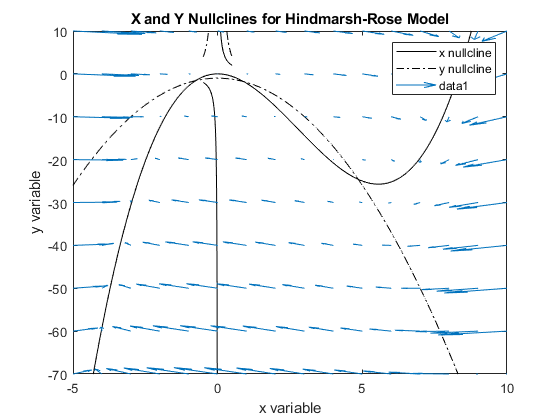

% Velocity maps
a = 0.3;
b = 2.5;
c = -1.;
d = 1.0;
[X,Y] = meshgrid(-5:10,-70:10:10); %Make a grid over x and y
xvec = -a.*X.^3 + b.*X.^2 + Y; %create x vector
yvec = -d.*X.^2 -Y + c; %create y vector
quiver(X,Y,xvec,yvec,0.3); %Plot Velocity Vector Field